% SNR table data
SNR = [8.4, 11.55, 7.85, 6.05, 4.5, 4.3;        8, 10.25, 8.8, 7.6, 6.6, 5.55;       8.35, 10.2, 7.9, 9.8, 7.5, 6.45;       8.03, 10.18, 8.5, 7.7, 8.35, 6.95;       7.64, 10.04, 7.75, 7.9, 7.3, 6.7;       3.88, 5.35, 5.65, 6.2, 5.3, 4.85];

% RSSI table data
RSSI = [-92.8, -93.8, -110, -110.8, -111.2, -111.9;        -91, -92.6, -109.8, -110.6, -109.4, -109;        -89.2, -91.8, -108.4, -109.6, -108.25, -108.2;        -87.28, -91.83, -108, -108.6, -108.6, -108.8;        -80.5, -91, -105.1, -108.2, -108, -108.5;        -81.33, -90.6, -103, -107.8, -106, -106.8];

% Packet loss data
packet_loss = [0.54, 0, 0, 0, 0, 0;               0.375, 0, 0, 0, 0, 0;               0.285, 0, 0, 0, 0, 0;               0.166, 0, 0, 0, 0, 0;               0, 0, 0, 0, 0, 0;               0, 0, 0, 0, 0, 0];

% Coding rate data
coding_rate = [9.75, 8.88, 8, 5.65];

% Bandwidths and Spreading Factors
BW = [10.4, 20.8, 62.5, 125, 250, 500];
SF = [7, 8, 9, 10, 11, 12];

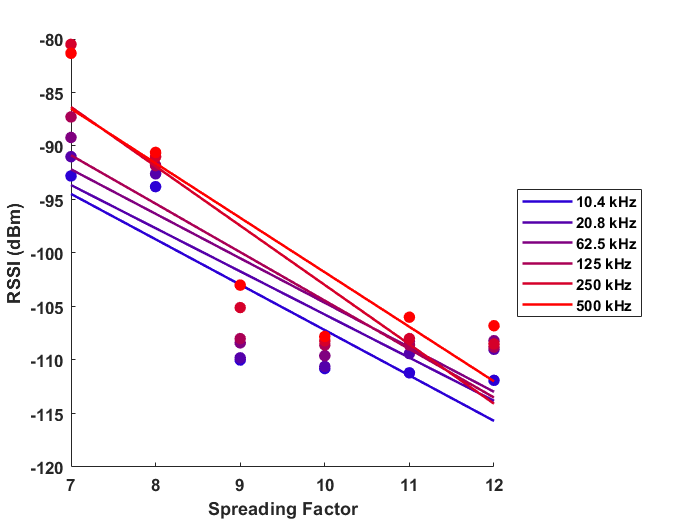

% Plotting the trend line for RSSI vs. Spreading Factor
figure;
hold on;
for i = 1:length(BW)
    p = polyfit(SF, RSSI(i,:), 1);
    y = polyval(p, SF);
    plot(SF, y, '-', 'Color', [i/length(BW), 0, 1-(i/length(BW))], 'LineWidth', 1.5, 'DisplayName', sprintf('%g kHz', BW(i)));
    scatter(SF, RSSI(i,:), 40, 'Marker', 'o', 'MarkerEdgeColor', [i/length(BW), 0, 1-(i/length(BW))], 'MarkerFaceColor', [i/length(BW), 0, 1-(i/length(BW))], 'HandleVisibility','off');
end

% Bold the x-axis label
xlabel('Spreading Factor', 'FontWeight', 'bold');

% Bold the y-axis label
ylabel('RSSI (dBm)', 'FontWeight', 'bold');

% Bold the title
%title('RSSI vs. Spreading Factor for Different Bandwidths with Trend Lines', 'FontWeight', 'bold');

% Display the legend and set its location
lgd = legend('show','Location',"eastoutside");

% Bold the legend
set(lgd, 'FontWeight', 'bold');

% Get the current axes handle
ax = gca;

% Bold the tick labels of the axes
set(ax, 'FontWeight', 'bold');

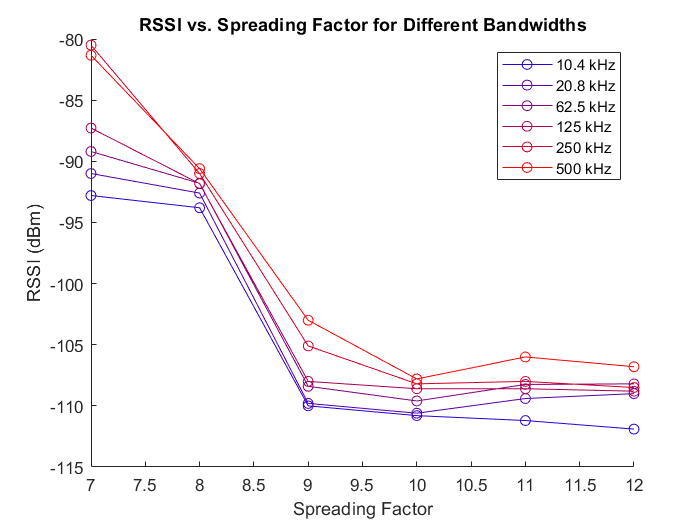


% Plotting the RSSI data
figure;
hold on;
for i = 1:length(BW)
    plot(SF, RSSI(i,:), '-o', 'Color', [i/length(BW), 0, 1-(i/length(BW))], 'DisplayName', sprintf('%g kHz', BW(i)));
end
xlabel('Spreading Factor');
ylabel('RSSI (dBm)');
title('RSSI vs. Spreading Factor for Different Bandwidths');
legend('show');

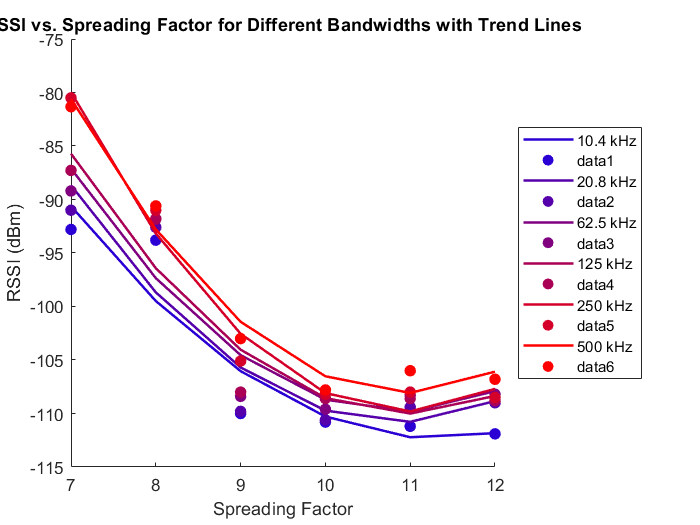


% Plotting the trend line for RSSI vs. Spreading Factor
figure;
hold on;
for i = 1:length(BW)
p = polyfit(SF, RSSI(i,:), 2);
y = polyval(p, SF);
plot(SF, y, '-', 'Color', [i/length(BW), 0, 1-(i/length(BW))], 'LineWidth', 1.5, 'DisplayName', sprintf('%g kHz', BW(i)));
scatter(SF, RSSI(i,:), 40, 'Marker', 'o', 'MarkerEdgeColor', [i/length(BW), 0, 1-(i/length(BW))], 'MarkerFaceColor', [i/length(BW), 0, 1-(i/length(BW))]);
end
xlabel('Spreading Factor');
ylabel('RSSI (dBm)');
title('RSSI vs. Spreading Factor for Different Bandwidths with Trend Lines');
legend('show','Location',"eastoutside");

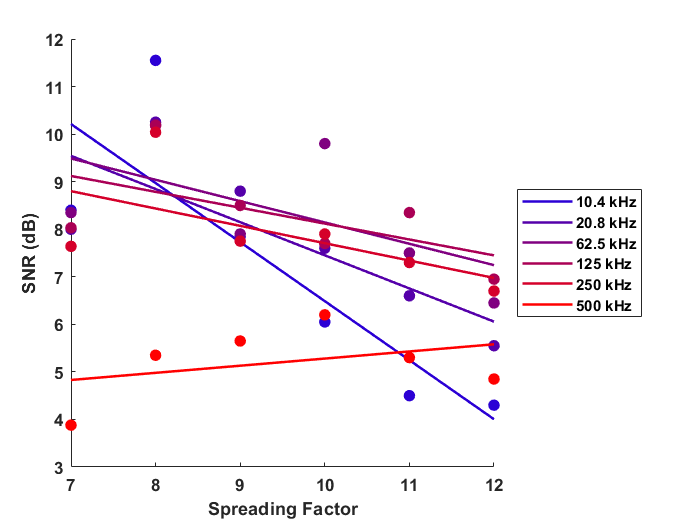

% Plotting the trend line for SNR vs. Spreading Factor
figure;
hold on;
for i = 1:length(BW)
    p = polyfit(SF, SNR(i,:), 1);
    y = polyval(p, SF);
    plot(SF, y, '-', 'Color', [i/length(BW), 0, 1-(i/length(BW))], 'LineWidth', 1.5, 'DisplayName', sprintf('%g kHz', BW(i)));
    scatter(SF, SNR(i,:), 40, 'Marker', 'o', 'MarkerEdgeColor', [i/length(BW), 0, 1-(i/length(BW))], 'MarkerFaceColor', [i/length(BW), 0, 1-(i/length(BW))], 'HandleVisibility','off');
end

% Bold the x-axis label
xlabel('Spreading Factor', 'FontWeight', 'bold');

% Bold the y-axis label
ylabel('SNR (dB)', 'FontWeight', 'bold');

% Bold the title
%title('SNR vs. Spreading Factor for Different Bandwidths with Trend Lines', 'FontWeight', 'bold');

% Display the legend and set its location
lgd = legend('show','Location',"eastoutside");

% Bold the legend
set(lgd, 'FontWeight', 'bold');

% Get the current axes handle
ax = gca;

% Bold the tick labels of the axes
set(ax, 'FontWeight', 'bold');

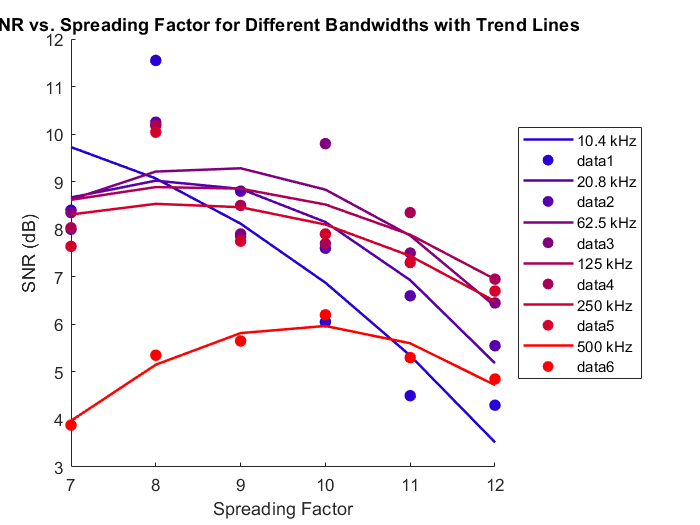


% Plotting the trend line for SNR vs. Spreading Factor
figure;
hold on;
for i = 1:length(BW)
p = polyfit(SF, SNR(i,:), 2);
y = polyval(p, SF);
plot(SF, y, '-', 'Color', [i/length(BW), 0, 1-(i/length(BW))], 'LineWidth', 1.5, 'DisplayName', sprintf('%g kHz', BW(i)));
scatter(SF, SNR(i,:), 40, 'Marker', 'o', 'MarkerEdgeColor', [i/length(BW), 0, 1-(i/length(BW))], 'MarkerFaceColor', [i/length(BW), 0, 1-(i/length(BW))]);
end
xlabel('Spreading Factor');
ylabel('SNR (dB)');
title('SNR vs. Spreading Factor for Different Bandwidths with Trend Lines');
legend('show','Location',"eastoutside");

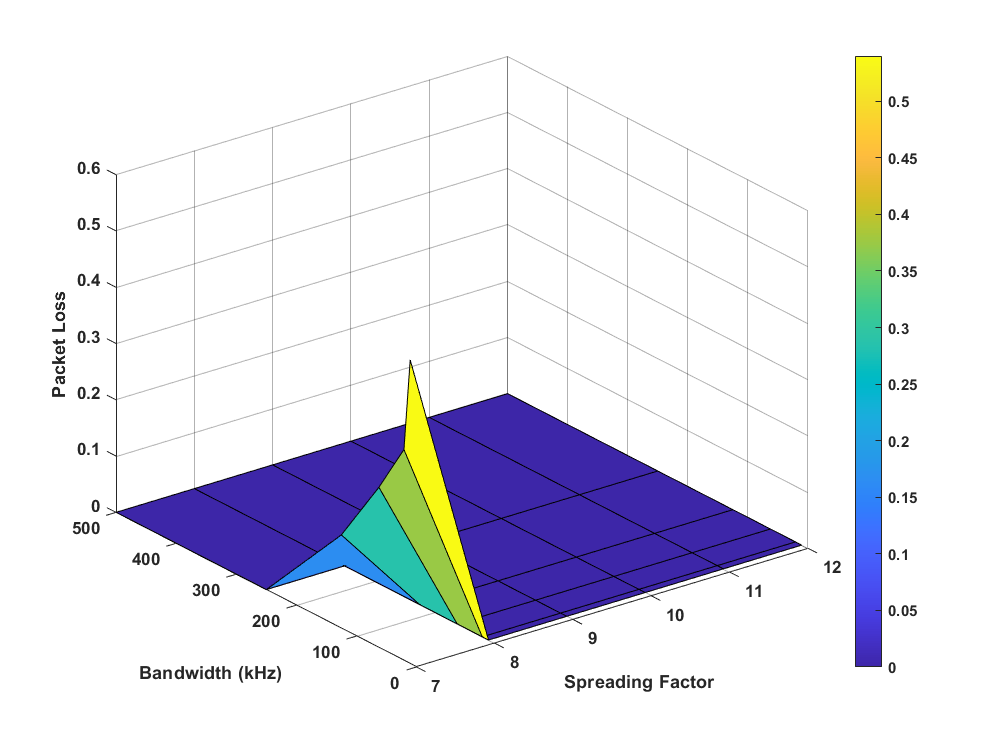

% Load data
packetLoss = [0.54 0 0 0 0 0; 0.375 0 0 0 0 0; 0.285 0 0 0 0 0; 0.166 0 0 0 0 0; 0 0 0 0 0 0; 0 0 0 0 0 0];

% Plot packet loss vs SF and BW
figure;
figure('Renderer', 'painters', 'Position', [100 100 800 600]);
surf(SF, BW, packetLoss);

% Bold the title
%title('Packet Loss vs Spreading Factor and Bandwidth', 'FontWeight', 'bold');

% Bold the x-axis label
xlabel('Spreading Factor', 'FontWeight', 'bold');

% Bold the y-axis label
ylabel('Bandwidth (kHz)', 'FontWeight', 'bold');

% Bold the z-axis label
zlabel('Packet Loss', 'FontWeight', 'bold');

colorbar;

% Get the current axes handle
ax = gca;

% Bold the tick labels of the axes
set(ax, 'FontWeight', 'bold');

% Set grid properties
ax.GridColor = [0 0 0]; % Black color
ax.GridAlpha = 0.3; % Transparency (0 is fully transparent, 1 is fully opaque)

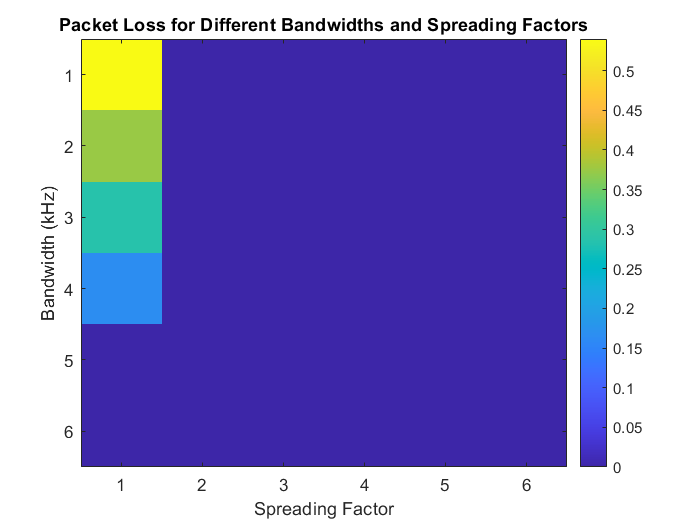

% Plotting the packet loss data
figure;
imagesc(packet_loss);
xlabel('Spreading Factor');
ylabel('Bandwidth (kHz)');
title('Packet Loss for Different Bandwidths and Spreading Factors');
colorbar;

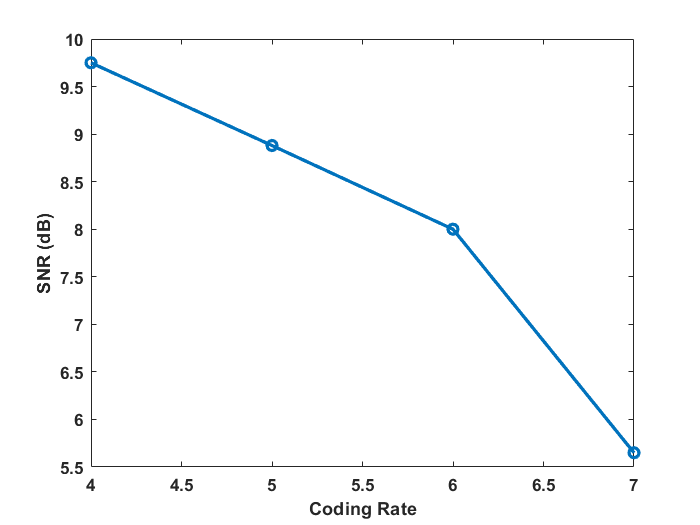

figure;
cr = [4:1:7];
snrr = [9.75,8.88,8,5.65];
plot(cr, snrr, '-o',"LineWidth",2);

% Bold the x-axis label
xlabel('Coding Rate', 'FontWeight', 'bold');

% Bold the y-axis label
ylabel('SNR (dB)', 'FontWeight', 'bold');

% Bold the title
%title('SNR vs. Coding Rate for 250 kHz Bandwidth', 'FontWeight', 'bold');

% Get the current axes handle
ax = gca;

% Bold the tick labels of the axes
set(ax, 'FontWeight', 'bold');